# Compare the **Eigenaxis** representation and the **Euler-Rodrigues** representation

**NOTE:**

- This tutorial demonstrates how to use the `bh_eul_eigenaxis_CLS` for representing the Eigenaxis approach of angular pose 

- Access to the Aerospace Toolbox is required for the functions [`dcm2rod`](matlab:  web(fullfile(docroot, 'aerotbx/ug/dcm2rod.html')))

## **Import the package:**

import bh_rots_PKG.*

## A refresher on  DCM - via Euler angles

syms phi theta psi

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [phi, theta, psi],'SYM');

And look at what you have - here's the DCM

- $^Bv = {^BR_G}.^Gv$      where   $ {^BR_G} = 
R_{3X}(Roll) \enspace . \enspace 
R_{2Y}(Pitch)\enspace . \enspace R_{1Z}(Yaw)$   

tmp_R3R2R1 = OBJ_pass_rot.get_R3R2R1

$$tmp\_R3R2R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & -\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Here are the 3 individual PASSIVE rotation matrices:

tmp_R1 = OBJ_pass_rot.get_R1

$$tmp\_R1 = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ -\sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

tmp_R2 = OBJ_pass_rot.get_R2

$$tmp\_R2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

tmp_R3 = OBJ_pass_rot.get_R3

$$tmp\_R3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Create a reference DCM - via Euler angles

#### Specify the angles

ref_yaw_deg   = 190;
ref_pitch_deg = 60;
ref_roll_deg  = 40;
ref_YPR_deg   = [ref_yaw_deg, ref_pitch_deg, ref_roll_deg];

#### Create the DCM

OBJ_pass_rot = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, ref_YPR_deg,'DEGREES');
 
 ref_DCM_bRg  = OBJ_pass_rot.get_R3R2R1 

ref_DCM_bRg =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


Plot stuff

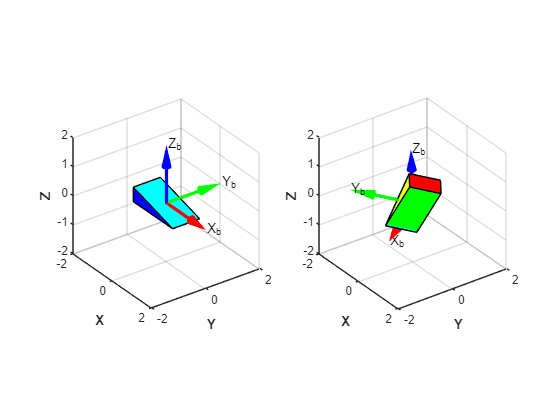

hfig =  figure;
hax(1) = subplot(1,2,1);
         LOC_plot_stuff(eye(3), hfig, hax(1));
            hold on
hax(2) = subplot(1,2,2);
         LOC_plot_stuff(ref_DCM_bRg, hfig, hax(2));           

## Explore the Eigenaxis representation - part 1

### Play with the Eigenaxis object - create using a DCM:

Say you have a DCM:

ref_DCM_bRg 

ref_DCM_bRg =    -0.4924   -0.0868   -0.8660
   -0.4152   -0.8511    0.3214
   -0.7650    0.5178    0.3830


Create the Eigenaxis object:

 OBJ_ee = bh_eul_eigenaxis_CLS(ref_DCM_bRg)

OBJ_ee =   bh_eul_eigenaxis_CLS with properties:

            e_col: [3×1 double]
        theta_rad: 2.9424
    DCM_B_given_A: [3×3 double]
        theta_deg: 168.5871
           e_axis: [-0.4963 0.2554 0.8297]
      vis_DCM_bRg: [3×3 double]


So what is the **Eigenaxis** and **theta **and the** DCM**

OBJ_ee.e_col.'

ans =    -0.4963    0.2554    0.8297


OBJ_ee.theta_rad

ans = 2.9424

rad2deg(OBJ_ee.theta_rad)

ans = 168.5871

OK: Let's compare the Eigenaxis results against the  Euler-Rodrigues vector - see [`dcm2rod`](matlab:  web(fullfile(docroot, 'aerotbx/ug/dcm2rod.html'))). The Euler-Rodrigues vector has the form:

- 
$$\overrightarrow{b} \;=\;\left\lbrack \begin{array}{ccc}
b_X  & b_Y  & b_Z 
\end{array}\right\rbrack \;\;\;=\;\;\tan \left(\frac{\theta }{2}\right)\ldotp \left\lbrack \begin{array}{ccc}
s_X  & s_Y  & s_Z 
\end{array}\right\rbrack \;\;\;\textrm{where}\;\;\;1=\left|s\right|$$


b = dcm2rod(ref_DCM_bRg)

b =    -4.9669    2.5557    8.3032


s = b/norm(b)

s =    -0.4963    0.2554    0.8297


half_tan_theta = norm(b)

half_tan_theta = 10.0073

theta_deg = 2*atand(half_tan_theta)

theta_deg = 168.5871

# Local subfunctions only beyond this point

 function LOC_plot_stuff(DCM_bRg, hfig, hax)
  % ALLOWED USAGE:
  %   >> LOC_plot_stuff(DCM)
  %   >> LOC_plot_stuff(DCM, hfig, hax)  
  
    if(1==nargin)
        hfig = figure;
        hax  = axes();
    end
 
    import bh_rots_PKG.bh_vehicle_CLS
 
    DCM_gRb = DCM_bRg.';    
    
    veh_OBJ = bh_vehicle_CLS();              
    veh_OBJ = veh_OBJ.rotate_using_gRb(DCM_gRb);
    
    % plot stuff
    veh_OBJ.plot_3D(hax);
    
 end